clear;clc;close all;

%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = mat2gray(X(:,:,1:12));              %takes only first 12 frames   
[m,n,p] = size(X);  

%Using Gaussian Filter

h = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
[m1,n1] = size(h);   

%Building circularly blurred images

Y = zeros(m,n,p);
for i = 1:p
    Y(:,:,i) = blurryimage(X(:,:,i), h, [m,n]);
end

%% Creating a t-linear system corresponding to the deblurring problem

X_reorder = reorder_tensor(X,[m,n,p]);      %dimension n*p*m
Y_reorder = reorder_tensor(Y,[m,n,p]);

%Defining the t-linear measurement operator

A = circ_blurring_mxop(h, [m,n,p]);

%Initialisation

X0 = zeros(n,p,m);
Xblurry = Y_reorder;

%Deblurring Experiments for TRGS
its = 10000;
weights = ones(its,1);

%TRBAGS
[Z_reorder_a,res_errs_a] = TRBAGS_err_deblurring(A,Y_reorder,X0,its,X_reorder,5,weights);
[Z_reorder_blurry_a,res_errs_blurry_a] = TRBAGS_err_deblurring(A,Y_reorder,Xblurry,its,X_reorder,5,weights);

%TRBGS
[Z_reorder, res_errs] = TRBGS_err_deblurring(A,Y_reorder,X0,its,X_reorder,5)

Z_reorder = Z_reorder(:,:,1) =

   1.0e-10 *

    0.0146    0.0571    0.0624    0.0756    0.0932    0.0355   -0.0262   -0.0594   -0.0406   -0.0501   -0.0544   -0.0422
    0.0342   -0.0125    0.0103    0.0128   -0.0327    0.0841    0.1529    0.1999    0.1691    0.1523    0.1475    0.1180
    0.0453    0.0874    0.0430    0.0795    0.1018    0.0662    0.0486    0.0258    0.0161    0.0087    0.0226    0.0287
    0.0918    0.0122    0.0286    0.0242    0.0623   -0.1188   -0.2437   -0.2788   -0.2466   -0.1899   -0.2057   -0.1716
   -0.2859   -0.2057   -0.1962   -0.2705   -0.3142   -0.0961    0.0841    0.1391    0.1366    0.0938    0.1069    0.0760
    0.1518    0.1483    0.1511    0.2121    0.2259    0.1408    0.0369   -0.0003   -0.0055   -0.0059   -0.0141   -0.0036
    0.1001    0.0436    0.0389    0.0479    0.0226    0.0870    0.1404    0.1808    0.1530    0.1466    0.1443    0.1221
   -0.0928   -0.0373   -0.0639   -0.0712   -0.0304   -0.1178   -0.1549   -0.1998   -0.1774   -0.1613   -0.1

res_errs =   182.3673  159.6931  149.8797  137.6479  127.4458  116.9616  112.0054  106.1358  105.2735   91.2491   91.0590   81.3275   77.3417   62.1256   61.3342   55.6328   52.5432   51.7253   48.5346   48.1527   48.0053   47.0073   43.5413   43.3126   41.0279   40.4617   40.2207   39.7607   39.6622   37.7491   37.6352   36.9563   36.5105   36.3358   36.2317   35.6907   35.5327   35.3954   34.7522   34.4780   34.2508   34.1647   32.3817   32.2251   31.1857   30.9838   30.8431   30.7748   30.5184   30.3434


[Z_reorder_blurry,res_errs_blurry] =  TRBGS_err_deblurring(A,Y_reorder,Xblurry,its,X_reorder,5)

Z_reorder_blurry = Z_reorder_blurry(:,:,1) =

   1.0e-10 *

   -0.0767   -0.1081   -0.1111   -0.1869   -0.1970   -0.1884   -0.1940   -0.1448   -0.1569   -0.1434   -0.1331   -0.1451
    0.0088    0.0179    0.1071    0.1378    0.1161    0.1241    0.1002    0.0881    0.0461    0.0463    0.0135    0.0199
    0.0471    0.0798    0.0806    0.1205    0.1326    0.1482    0.1287    0.0839    0.1407    0.1334    0.1690    0.1489
   -0.0091   -0.0391   -0.1131   -0.1354   -0.1106   -0.1148   -0.0764   -0.0704   -0.0617   -0.0493   -0.0600   -0.0429
   -0.0095   -0.0013   -0.0194   -0.0227   -0.0417   -0.0825   -0.0646   -0.0314   -0.0680   -0.0843   -0.0911   -0.0768
   -0.0501   -0.0724   -0.0151   -0.0665   -0.0745   -0.0370   -0.0720   -0.0494   -0.0511   -0.0401   -0.0313   -0.0596
    0.0616    0.0954    0.1500    0.2264    0.2227    0.2258    0.2067    0.1537    0.1495    0.1484    0.1268    0.1393
    0.0225    0.0269   -0.0458   -0.0379   -0.0172   -0.0209   -0.0010   -0.0204    0.0350   

res_errs_blurry =   182.3673  162.3901  153.0059  136.4402  130.0271  126.8707  111.3176   99.7029   78.6867   77.2074   76.0968   75.2224   71.3904   69.4295   65.9690   63.1983   62.1830   59.7136   59.0730   58.0370   57.1147   51.7728   51.4703   50.1521   49.0093   48.6486   46.8898   42.7782   41.9163   41.8775   41.1409   40.9563   40.6322   40.5133   40.1556   39.6728   39.1043   38.0410   37.7343   37.5397   37.4509   36.8621   36.6260   33.3568   33.2309   32.8949   32.8707   32.4497   32.4017   31.5495



Z_a = recover_img(Z_reorder_a,[m,n,p]);
Z_blurry_a = recover_img(Z_reorder_blurry_a,[m,n,p]);

Z = recover_img(Z_reorder,[m,n,p]);
Z_blurry = recover_img(Z_reorder_blurry,[m,n,p]);

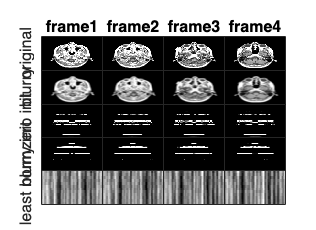

figure(1);
%trbags plots
h1a = semilogy(0:its,res_errs_a,'b--','LineWidth',2);
hold on
h2a = semilogy(0:its,res_errs_blurry_a,'b-','LineWidth',2);
hold on

%trbgs plots
h1 = semilogy(0:its,res_errs,'r--','LineWidth',2);
hold on
h2 = semilogy(0:its,res_errs_blurry,'r-','LineWidth',2);
hold off

xlabel('Iterations','FontSize',18,'Interpreter','latex') 
ylabel('Residual Error','FontSize',18,'Interpreter','latex') 
legend([h1(1),h2(1),h1a(1),h2a(1)],{'zero initialisation TRBGS', 'blurry initialisation TRBGS','zero initialisation TRBAGS', 'blurry initialisation TRBAGS'},'FontSize',13,'Interpreter','latex','Location','northeast')
%title("Deblurring using FacTRK",'FontSize',18)

set(gcf,'position',[10,10,550,400])
set(gca,'FontSize',16)
savefig('TBRGS_deblurring_error_diff_initialization.fig')
saveas(gca,'TBRGS_deblurring_error_diff_initialization.png')

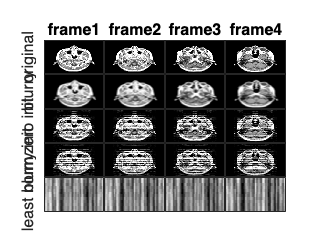

clear res_errs res_errs_a res_errs_blurry res_errs_blurry_a
clear Z_reorder_blurry Z_reorder_blurry_a Z_reorder Z_reorder_a
clear X_reorder Y_reorder

X_ln = tprod(tpinv(A),reorder_tensor(Y,[m,n,p]));
clear A

t = tiledlayout(5,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i),[0,1]);%colormap gray
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("zero init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_blurry(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

% for i = 1:4
%     nexttile;
%     imagesc(Z_rand(:,:,i));colormap gray
%     %axis equal
%     %axis tight
%     if i == 1
%         ylabel("rand init",'FontSize',8);
%     end
%     grid off
%     set(gca,'TickLength',[0 0])
%     set(gca,'Yticklabel',[]) 
%     set(gca,'Xticklabel',[])
% end

%calculate least-norm solution
for i = 1:4
    nexttile;
    imagesc(permute(X_ln(:,:,i),[2,1,3]));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); %x_width=10cm y_width=15cm

savefig('TRBGSdeblurring_diff_initialization.fig')
saveas(gcf,'TRBGSdeblurring_diff_initialization.png')

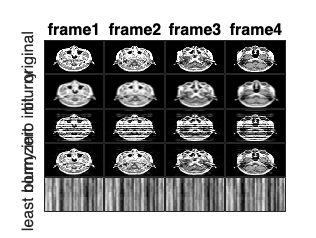

ta = tiledlayout(5,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i),[0,1]);%colormap gray
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_a(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("zero init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_blurry_a(:,:,i),[0,1]);%colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

% for i = 1:4
%     nexttile;
%     imagesc(Z_rand(:,:,i));colormap gray
%     %axis equal
%     %axis tight
%     if i == 1
%         ylabel("rand init",'FontSize',8);
%     end
%     grid off
%     set(gca,'TickLength',[0 0])
%     set(gca,'Yticklabel',[]) 
%     set(gca,'Xticklabel',[])
% end

%calculate least-norm solution
for i = 1:4
    nexttile;
    imagesc(permute(X_ln(:,:,i),[2,1,3]));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); %x_width=10cm y_width=15cm

savefig('TRBAGSdeblurring_diff_initialization.fig')
saveas(gcf,'TRBAGSdeblurring_diff_initialization.png')